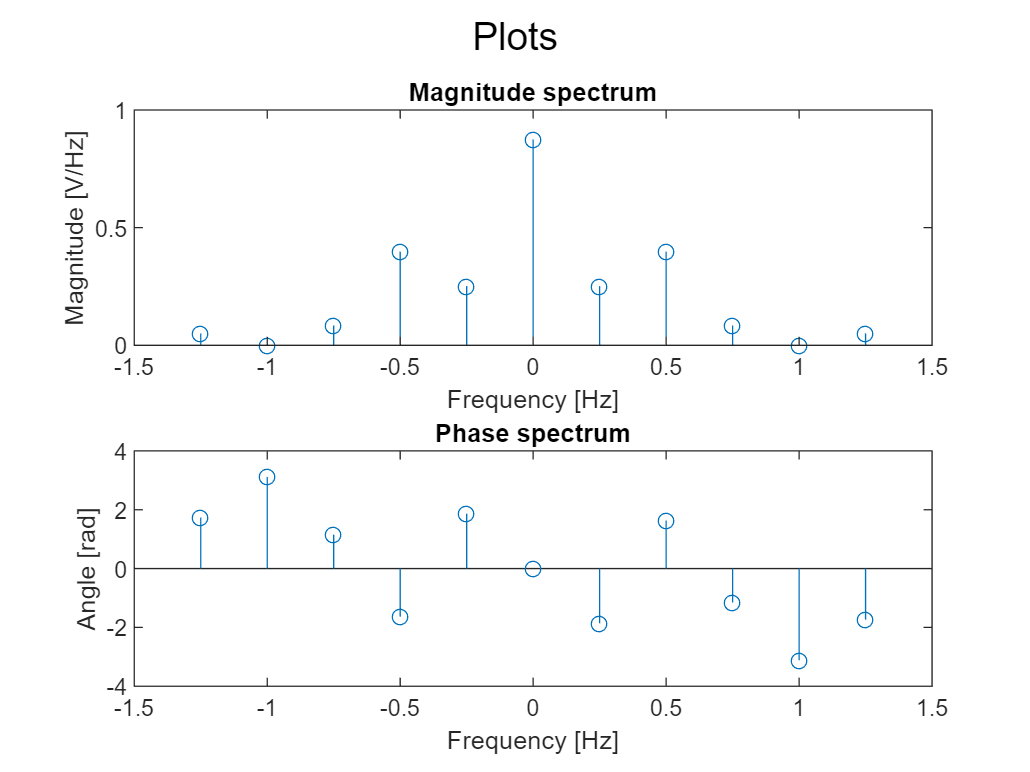

clear 
close all

%% 1
T = 4;
f0 = 1 / T;
fs = 100 / T; 
t0 = 0;
samples = 100;

t1 = linspace(t0, t0 + T, samples + 1);
t1(end) = [];

y1 = zeros(1, length(t1));
y1(t1 < 1) = 0.5;
y1(1 <= t1 & t1 < 2) = 2;
y1(2 <= t1 & t1 < 3) = 0;
y1(3 <= t1 & t1 < 4) = 1;

%% 2
s1 = repmat(y1, [1, 5]);

%% 3
t = linspace(t0, t0 + 5 * T, 5 * samples + 1);
t(end) = [];

%% 4 
numHarm = 5;
n = 1:numHarm;
n1 = -numHarm:numHarm;

dt = t1(2) - t1(1);

% a0 = 1 / T * sum(y1) * dt;
% an = 2 / T * sum(y1 * cos(t1.' * 2 * pi * n / T), 1) * dt;
% bn = 2 / T * sum(y1 * sin(t1.' * 2 * pi * n / T), 1) * dt;
% 
% %% 5
% c0 = a0;
% cn = zeros([1, 2 * numHarm + 1]);
% cn(numHarm + 2:end) = 1 / 2 * (an - 1j * bn)
% cn(1:numHarm) = flip(1 / 2 * (an + 1j * bn))
% 
% cn(numHarm + 1) = c0;

[~, cn, c0, an, bn] = FourierSeries(y1, t1, t, numHarm);

%% 6

subplot(2, 1, 1)
stem(-numHarm*f0:f0:f0*numHarm, abs(cn))
title("Magnitude spectrum")
xlabel("Frequency [Hz]")
ylabel("Magnitude [V/Hz]")

subplot(2, 1, 2)
stem(-numHarm*f0:f0:f0*numHarm, angle(cn))
title("Phase spectrum")
xlabel("Frequency [Hz]")
ylabel("Angle [rad]")

sgtitle("Plots")

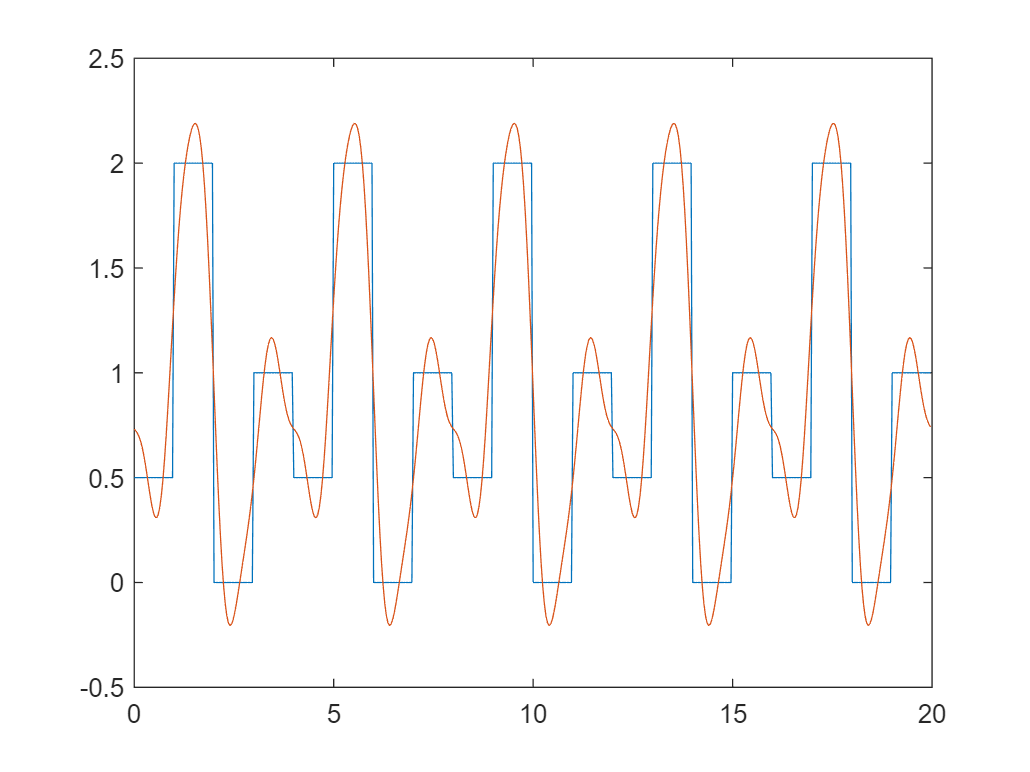

%% 7

y1_app = cn.' .* exp(1j * 2 * pi / T * n1.' * t);

%% 8
f1 = sum(y1_app, 1);

figure
plot(t, s1)
hold on
plot(t, f1)